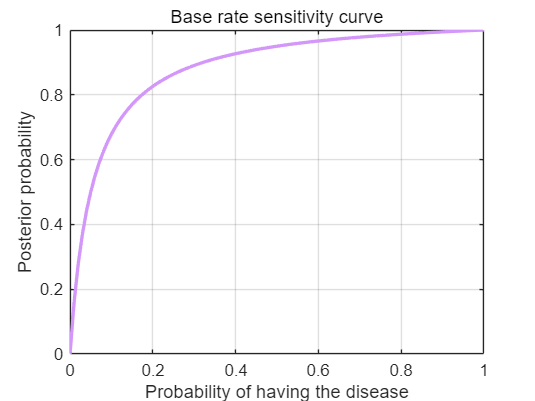

clear; clc; close all;
P_d = 0:0.01:1;
P_t_on_d = 0.95;
P_t_on_nd = 0.05;
P_d_on_t = (P_t_on_d * P_d) ./ ((P_t_on_d * P_d) + (P_t_on_nd * (1 - P_d)));
plot(P_d, P_d_on_t, 'Color', [211/255, 150/255, 249/255], 'LineStyle', '-', 'LineWidth', 2);
title('Base rate sensitivity curve');
xlabel('Probability of having the disease');
ylabel('Posterior probability');
grid on;